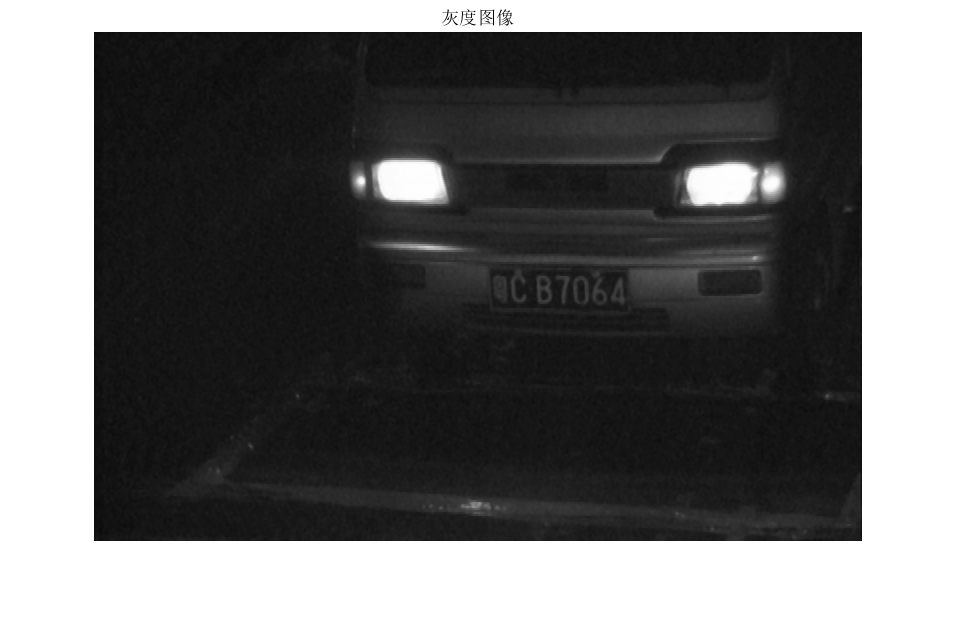

clc;clear;close all;
img = imread('images\challenging\04_1.jpg');
% 蓝色背景1，黄色背景2，其他3
color = 3;
% imshow(img);title('原始图像');

img_gray = preprocess(img);
imshow(img_gray);title("灰度图像");

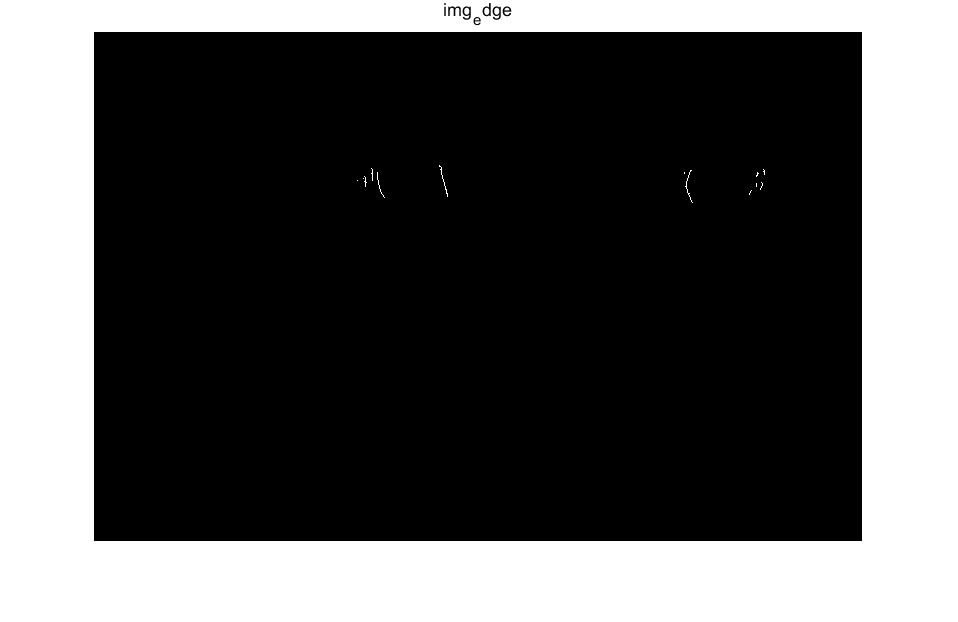


[sobel_vertical,Prewitt_vertical,Roberts_vertical,log_vertical,Canny_vertical] = edge_detect(img_gray);
img_edge = Prewitt_vertical;
imshow(img_edge);title("img_edge");

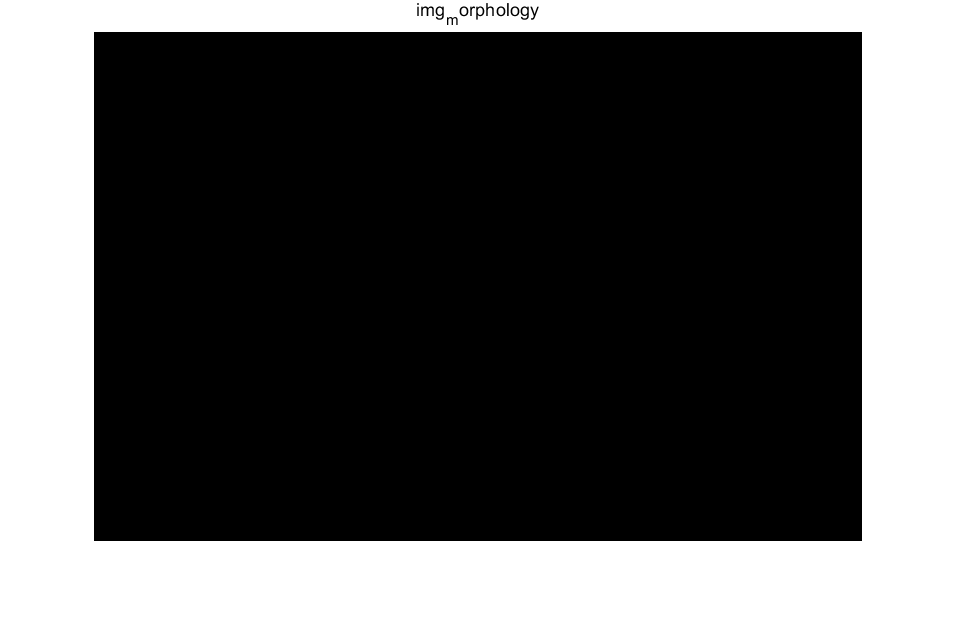



[img_morphology,bw_close,bw_remvoe,bw_open] = morphology(img_edge,1000);
% imshow(bw_close);title("bw_close");
% imshow(bw_remvoe);title("bw_remvoe");
% imshow(bw_open);title("bw_open");
imshow(img_morphology);title("img_morphology");

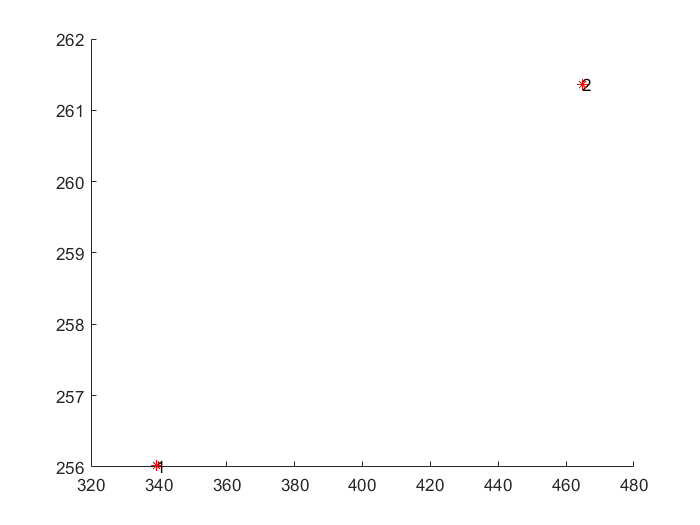

车牌候选区域的数量:2 


index_area =      0     1


index_color =      0     0


index_ratio =      0     1


index_sum =      0     2


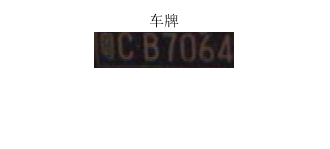


img_morphology = judge(img_morphology,img);
img_mask = area_select(img_morphology,img,color);